# ______________Computational Electromagnetics 

## _______________________________ Hw6-Q1

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/09/27        

clear; clc; close all;

## Galerkin Method:


syms x n m

f(x,n) =   x - x^(n+1);
W(x,m) =   x - x^(m+1);
g(x)   = 1 + 4*x^3; 

lmn(m,n) = int( -diff(f(x,n),x,2)*W(x,m) , x, [0 1]  ) ;

gm(m)  = int(g(x)*W(x,m) , x, [0 1]);


N=1;
[Alpha_N1 , G_N1 , L_N1 ] = Galerkin_Meth_Mine(N,lmn,gm);

N=2;
[Alpha_N2 , G_N2 , L_N2 ] = Galerkin_Meth_Mine(N,lmn,gm);

N=3;
[Alpha_N3 , G_N3 , L_N3 ] = Galerkin_Meth_Mine(N,lmn,gm);

N=4;
[Alpha_N4 , G_N4 , L_N4 ] = Galerkin_Meth_Mine(N,lmn,gm);

N=5;
[Alpha_N5 , G_N5 , L_N5 ] = Galerkin_Meth_Mine(N,lmn,gm);

Alpha = {Alpha_N1 ; Alpha_N2 ; Alpha_N3;  Alpha_N4; Alpha_N5 };

f_exact(x)  = -1/10* x *(-17 + 5*x + 2*x^4);
X = 0.001: 0.01 : 1; 

Answers = zeros(length(Alpha),length(X));

for i=1:length(Alpha)
    Coeff = Alpha(i);
    Coeff = Coeff{1};
    Answers(i,:) = X;
    for j=1:length(Coeff)
        
    Answers(i,:)  =  Answers(i,:) + Coeff(j)*(X  - X.^(j+1)   );
    end
end

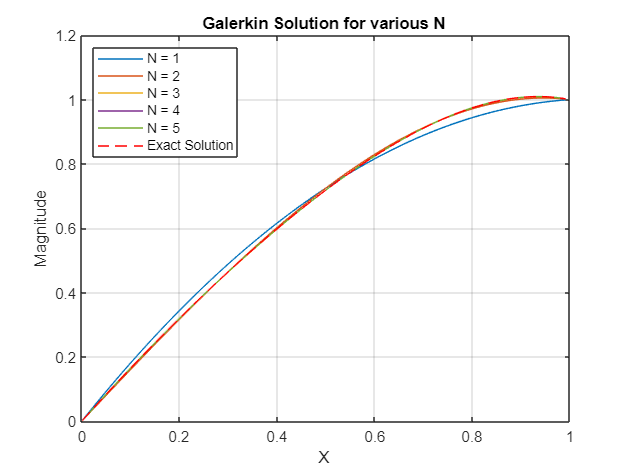

close all;
figure(1)
plot(X, Answers)
hold on
Legend = cell(1,length(Alpha)+1);
for i=1:length(Alpha)
    Legend(i) =  {"N = "+ num2str(length(Alpha{i}))} ;
end
plot(X,double(f_exact(X) ) , 'r--' )
Legend(i+1) =  { "Exact Solution" }  ; 
legend(Legend,"Location",'northwest');

title(" Galerkin Solution for various N  ")
xlabel(" X  ")
grid on
ylabel("Magnitude")

% Calculate the L2 Error:

Error  = sum( ( repmat( double(f_exact(X)) , length(Alpha)  ,1   )   - Answers ).^2 , 2 )  ; 
format long
disp(Error)

It can be observed that the error is almost 0 for n=4 and n=5;

function [Alpha , G , L ]=Galerkin_Meth_Mine(N,lmn,gm)
L = zeros(N,N);
G = zeros(N,1);

for i=1:N
    for j=1:N
        
        L(i,j) = double(lmn(i,j))  ;

    end

    G(i)  = double(gm(i)); 

end


Alpha = L\G;

end


